# Example Uses of SMOTE Function

## **Prepare Dataset**

clc
clear
load fisheriris % Load example dataset
% Remove observations from two classes to simulate one majority class and 
% two minority classes
I = [1:50 51:75 101:125]; % Exclude some samples to create an unbalanced dataset
meas = meas(I,:);
species = categorical(species(I));
% Prepare some variables for use in plotting results of examples
us = unique(species);
c = 'rbg';

## Example 1: Balance Dataset

Use SMOTE to balance dataset (using default 5 k-nearest neighbors)

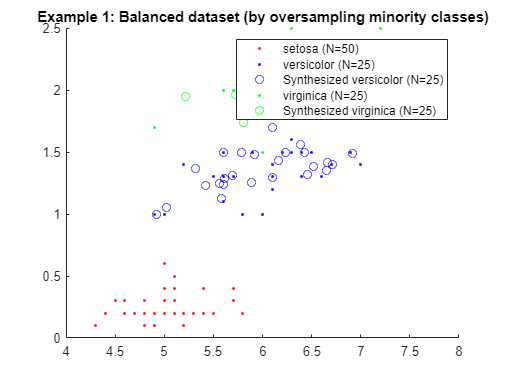

rng(42)
[meas1,species1,new_meas,new_species] = smote(meas, [], 'Class', species);
K = groupcounts(species);
figure,hold on
legend_str = {};
for ii=1:numel(us)
    I = species==us(ii);
    plot(meas(I,1),meas(I,4),'.','Color',c(ii));
    legend_str{end+1} = sprintf('%s (N=%d)', us(ii) ,K(ii));
    I = new_species==us(ii);
    if sum(I)>0
        plot(new_meas(I,1),new_meas(I,4),'o','Color',c(ii));
        legend_str{end+1} = sprintf('Synthesized %s (N=%d)', us(ii), K(ii));
    end
end
legend(legend_str)
title('Example 1: Balanced dataset (by oversampling minority classes)')

## Example 2: Oversample All Classes

Use SMOTE to oversample all classes 100% (using default 5 k-nearest neighbors)

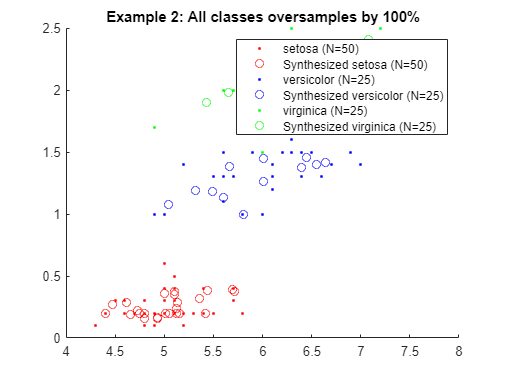

rng(42)
[meas2,species2,new_meas,new_species] = smote(meas, .5, 'Class', species);
K = groupcounts(species);
figure,hold on
legend_str = {};
for ii=1:numel(us)
    I = species==us(ii);
    plot(meas(I,1),meas(I,4),'.','Color',c(ii));
    legend_str{end+1} = sprintf('%s (N=%d)', us(ii) ,K(ii));
    I = new_species==us(ii);
    if sum(I)>0
        plot(new_meas(I,1),new_meas(I,4),'o','Color',c(ii));
        legend_str{end+1} = sprintf('Synthesized %s (N=%d)', us(ii), K(ii));
    end
end
legend(legend_str)
title('Example 2: All classes oversamples by 100%')

## Example 3: Oversample One Class

Use SMOTE to oversample first class 200%, and leave the rest as they are (using 10 k-nearest neighbors)

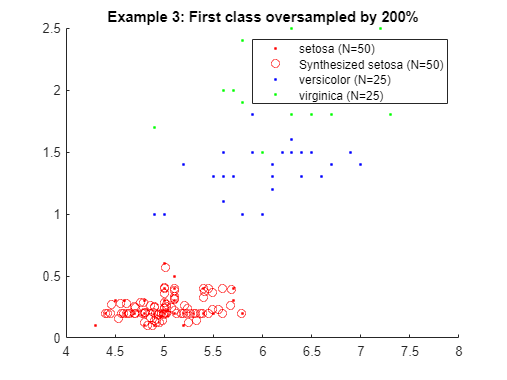

rng(42)
[meas3,species3,new_meas,new_species] = smote(meas, [2 0 0], 10, 'Class', species);
K = groupcounts(species);
figure,hold on
legend_str = {};
for ii=1:numel(us)
    I = species==us(ii);
    plot(meas(I,1),meas(I,4),'.','Color',c(ii));
    legend_str{end+1} = sprintf('%s (N=%d)', us(ii) ,K(ii));
    I = new_species==us(ii);
    if sum(I)>0
        plot(new_meas(I,1),new_meas(I,4),'o','Color',c(ii));
        legend_str{end+1} = sprintf('Synthesized %s (N=%d)', us(ii), K(ii));
    end
end
legend(legend_str)
title('Example 3: First class oversampled by 200%')